% Create optimization variables
numAnd2 = optimvar("numAnd","Type","integer","LowerBound",1,"UpperBound",2);
numOr2 = optimvar("numOr","Type","integer","LowerBound",1,"UpperBound",2);
weight = optimvar("weight",1,3,"LowerBound",0.5,"UpperBound",1);
numDefuzzi = optimvar("numDefuzzi","Type","integer","LowerBound",1,...
    "UpperBound",4);
parameter1 = optimvar("parameter1",4,3,"LowerBound",-0.5,"UpperBound",0.5);
parameter2 = optimvar("parameter2",4,3,"LowerBound",-2,"UpperBound",2);
numHiddenUnits = optimvar("numHiddenUnits","Type","integer","LowerBound",1,...
    "UpperBound",4);
numLearningRate = optimvar("numLearningRate","Type","integer","LowerBound",1,...
    "UpperBound",3);

% Set initial starting point for the solver
initialPoint5.numAnd = ones(size(numAnd2));
initialPoint5.numOr = ones(size(numOr2));
initialPoint5.weight = ones(size(weight));
initialPoint5.numDefuzzi = ones(size(numDefuzzi));
initialPoint5.parameter1 = zeros(size(parameter1));
initialPoint5.parameter2 = zeros(size(parameter2));
initialPoint5.numHiddenUnits = repmat(2,size(numHiddenUnits));
initialPoint5.numLearningRate = ones(size(numLearningRate));

% Create problem
problem = optimproblem("ObjectiveSense","Maximize");

% Define problem objective
problem.Objective = fcn2optimexpr(@Fuzzy_GA_IMU,input,numAnd2,numOr2,weight,...
    numDefuzzi,parameter1,parameter2,numHiddenUnits,numLearningRate);

The accuarcy is 28.5714%
 AndMethod = min + OrMethod = max + rules weights of 0.75 and 0.75 and 0.75 + DefuzzificationMethod = lom + parameter1 = 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + 1.1102e-16 + parameter2 = 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + 4.4409e-16 + Hiddenunit of 20 + LearningRate of 0.01
---------------------------------------------------------------------------------------------------------------------------------------------


Solving problem using ga.
The accuarcy is 44.7619%
 AndMethod = min + OrMethod = max + rules weights of 0.96143 and 0.5381 and 0.72421 + DefuzzificationMethod = mom + parameter1 = -0.4873 + 0.1098 + 0.13642 + -0.069427 + -0.47897 + 0.25312 + -0.41597 + 0.12368 + -0.36722 + parameter2 = -0.14707 + 1.0596 + 0.87887 + 0.89145 + -1.4131 + -1.1746 + 0.682 + 0.20327 + -1.3637 + Hiddenunit of 40 + LearningRate of 0.01
---------------------------------------------------------------------------------------------------------------------------------------------
The accuarcy is 41.9048%
 AndMethod = prod + OrMethod = max + rules weights of 0.90149 and 0.79222 and 0.85844 + DefuzzificationMethod = centroid + parameter1 = 0.094432 + -0.19255 + -0.4922 + 0.24828 + -0.48899 + -0.025031 + 0.095059 + -0.16781 + -0.037595 + parameter2 = -0.97909 + -0.00041487 + -1.4352 + -1.8231 + -0.13941 + -1.1396 + -1.0777 + -0.85567 + -0.43249 + Hiddenunit of 5 + LearningRate of 0.01
---------------------------------

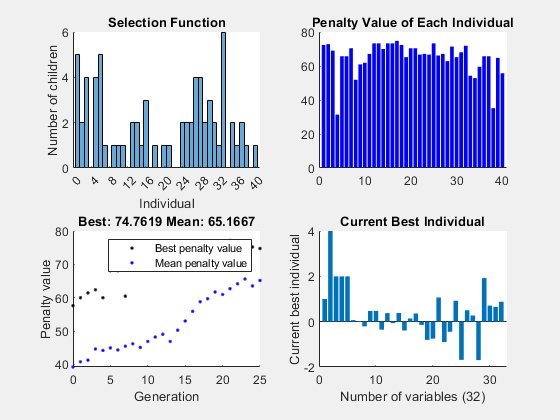

The accuarcy is 71.4286%
 AndMethod = prod + OrMethod = max + rules weights of 0.70671 and 0.65359 and 0.88039 + DefuzzificationMethod = som + parameter1 = 0.070343 + 0.47738 + 0.028712 + -0.34969 + -0.3889 + 0.37511 + 0.46977 + -0.066012 + 0.36288 + parameter2 = -0.14248 + -0.89913 + -0.80381 + -0.44596 + 0.27298 + 0.92218 + 1.0654 + -1.6832 + 1.9189 + Hiddenunit of 10 + LearningRate of 0.01
---------------------------------------------------------------------------------------------------------------------------------------------
Optimization terminated: maximum number of generations exceeded.



% Set nondefault solver options
options3 = optimoptions("ga","EliteCount",3,"MaxGenerations",25,...
    "PopulationSize",40,"PlotFcn",["gaplotselection","gaplotscores",...
    "gaplotbestf","gaplotbestindiv"]);

% Solve problem
[solution,objectiveValue] = solve(problem,initialPoint5,"Solver","ga",...
    "Options",options3);


% Display results
solution

solution = struct with fields:
             numAnd: 1
         numDefuzzi: 4
     numHiddenUnits: 2
    numLearningRate: 2
              numOr: 2
         parameter1: [4×3 double]
         parameter2: [4×3 double]
             weight: [0.7067 0.6536 0.8804]


objectiveValue

objectiveValue = 71.4286


% Clear variables
clearvars numAnd2 numOr2 weight numDefuzzi parameter1 parameter2 numHiddenUnits...
    numLearningRate initialPoint5 options3 objectiveValue
